# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# 6G Waveforms Proposals

## Introduction

In this second notebook of the sixth module, we will focus on the **Frequency Modulated OFDM (FM-OFDM)** strategy. After introducing **CE-OFDM** in the first part, we now dive deeper into the design, characteristics, and implementation details of **FM-OFDM.**

This technique aims to combine the advantages of traditional OFDM with the benefits of frequency modulation, offering improvements in signal robustness and power efficiency, key goals for future **6G** wireless systems.

## Index

- Introduction to 6G

- Constant Envelope OFDM (CE-OFDM)

- Frequency modulated OFDM (FM- OFDM)

- Orthogonal Time Frequency Space (OTFS)

## 3. Frequency-modulated OFDM (FM-OFDM)

Before introducing the basic theory of this new technique, we must re-define the previous configuration parameters that were explained in the first notebook for CE-OFDM, and that are exactly the same as before.

N_OFDM=2048;
Ng=1/8*N_OFDM; 
fg_1=171;
fg_2=172;
Fs=20; %MHz
N_symb=100;   

After implenting and analyzing the first waverform proposal for 6G (CE-OFDM), we can explore the second alternative, in this case **FM-OFDM**, which uses as base signal the CE-OFDM generated before. However, instead of directly modulating the phase iself, the OFDM information-bearing signal **modulates the differences in the phase** rather than the phases themselves, therefore we are including the OFDM signal inside the frequency. 

This way of encoding the information makes it **more robust** to phase noise, Doppler and frequency offsets than CE-OFDM or CP-OFDM, because the instantaneous frequency tends to vary much more slowly than the instantaneous phase under such impairments.

However, in the same way as CE-OFDM, FM-OFDM also has the property of a constant envelope, as well as the ability to trade off performance against bandwidth, and the flexibility to freely allocate users and control information into subcarriers. But, on the other hand, it also shares some FM drawbacks, like the higher bandwidth expense. 

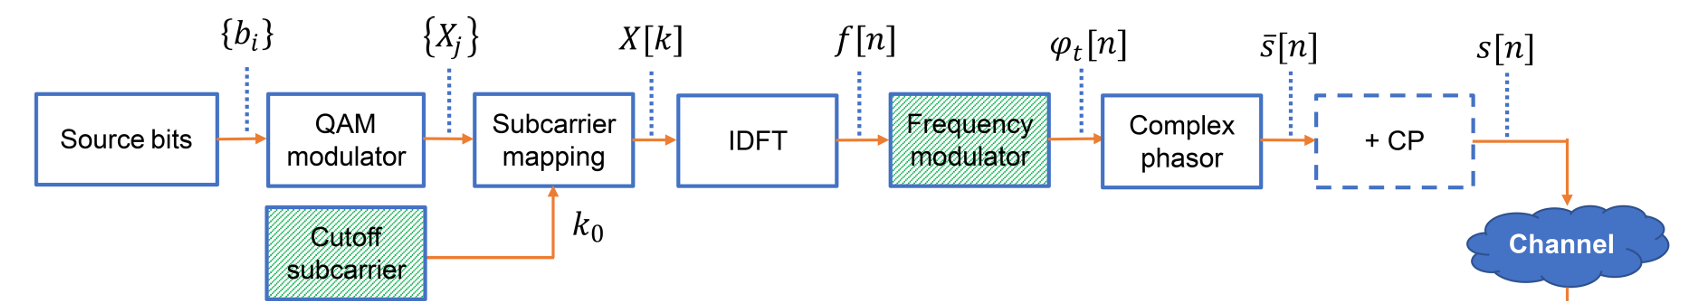

( Frequency-Modulated OFDM: A New Waveform for High-Mobility Wireless Communications,  *Javier Lorca Hernando and Ana García Armada* )

Now, we are going to extend the previously implemented **Constant Envelope OFDM (CE-OFDM)** to **Frequency Modulated OFDM (FM-OFDM)** by introducing an additional phase accumulation process. 

In FM-OFDM, instead of directly applying a phase shift, we accumulate the phase over time using the integral (cumulative sum) of the OFDM signal.

Mathematically, the instantaneous phase of the FM-OFDM signal is given by:


$$

\phi_{\text{FM}}(n) = 2\pi m \sum_{k=0}^{n} \frac{\text{OFDM}[k]}{\sqrt{N_{\text{OFDM}}}}
$$


where ***m*** is the **modulation index**, controlling the frequency deviation of the FM signal.

The transmitted **FM-OFDM** signal is then obtained as:


$$\text{FM-OFDM}(n) = e^{j \phi_{\text{FM}}(n)}$$


This modulation technique preserves the constant envelope property of the signal while potentially altering its spectral occupancy.

Moreover,  we are going to study  the impact of the modulation index  on the spectrum, considering **two extreme values**:

- **Low Modulation Index: **$m_{\text{low}} = \frac{0.01}{2\pi}$

- **High Modulation Index:** $ m_{\text{high}} = \frac{0.6}{2\pi}$

A **low** modulation index should main a spectrum close to the original CE-OFDM, whereas a **high** modulation index causes a significant frequency spread due to the rapid phase variation introduced by the accumulated OFDM signal.

% Define modulation index
m_fm = 0.01/(2*pi); % Can be adjusted for spectral efficiency
m_fm2 = 0.6/(2*pi);

num_data_symbols = N_OFDM/2 - 1;

for symb=1:N_symb   

    % Generate QPSK symbols for positive frequencies
    i = sign(rand(1, num_data_symbols) - 0.5);
    q = sign(rand(1, num_data_symbols) - 0.5);
    qpsk_data = i + 1j * q;
    
    % Allocate OFDM array with Hermitian symmetry
    qpsk_ini = zeros(1, N_OFDM);
    
    % DC component (real)
    qpsk_ini(1) = sign(rand(1) - 0.5);
    
    % Positive frequencies (indices 2 to N_OFDM/2)
    qpsk_ini(2 : N_OFDM/2) = qpsk_data;
    
    % Nyquist component (real)
    qpsk_ini(N_OFDM/2 + 1) = sign(rand(1) - 0.5);
    
    % Negative frequencies: conjugate and reverse positive frequencies
    qpsk_ini(N_OFDM/2 + 2 : end) = conj(fliplr(qpsk_data));
    
    % Perform IFFT to get real-valued OFDM signal
    ofdm = N_OFDM*ifft(qpsk_ini, N_OFDM);
    
    % Apply FM modulation: integrate OFDM to get phase
    phi_fm = cumsum(ofdm) * 2*pi*m_fm/sqrt(N_OFDM); 
    phi_fm2 = cumsum(ofdm) * 2*pi*m_fm2/sqrt(N_OFDM);
    % Frequency-modulated OFDM signal
    fm_ofdm = exp(1j * phi_fm);
     % Frequency-modulated OFDM signal
    fm_ofdm2 = exp(1j * phi_fm2);
    
    % Add cyclic prefix
    fm_ofdm = [fm_ofdm(N_OFDM - Ng + 1 : N_OFDM), fm_ofdm];
    fm_ofdm2 = [fm_ofdm2(N_OFDM - Ng + 1 : N_OFDM), fm_ofdm2];

    % Store the transmitted signal
    signal_fm_ofdm(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = fm_ofdm;
    signal_fm_ofdm2(1, (symb - 1) * (N_OFDM + Ng) + 1 : symb * (N_OFDM + Ng)) = fm_ofdm2;

end

Before proceeding with the full FM-OFDM signal analysis, we can plot one of the cumulative phase signals, $\phi_{\text{FM}}$. This will help us visualize how the phase evolves over time when applying frequency modulation to the OFDM signal.

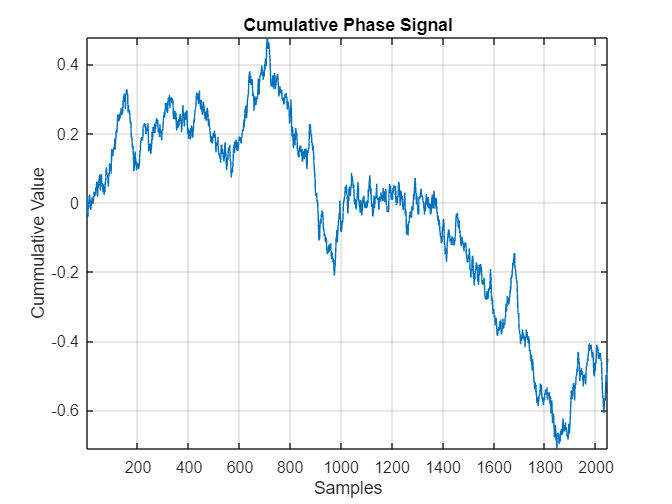

figure()
plot(phi_fm)
xlabel("Samples")
ylabel("Cummulative Value")

title("Cumulative Phase Signal")
grid on; 
axis tight;

While the original OFDM signal fluctuates rapidly due to the randomness of QPSK symbols, the cumulative sum $\phi_{\text{FM}}$ smooths out these rapid changes. Therefore, instead of abrupt transitions, we can observe a more continuous and slowly varying phase.

On the other hand, as we previously commented, the FM-OFDM signal mantains the property of having a constant envelope, which can be verified in the following representation:

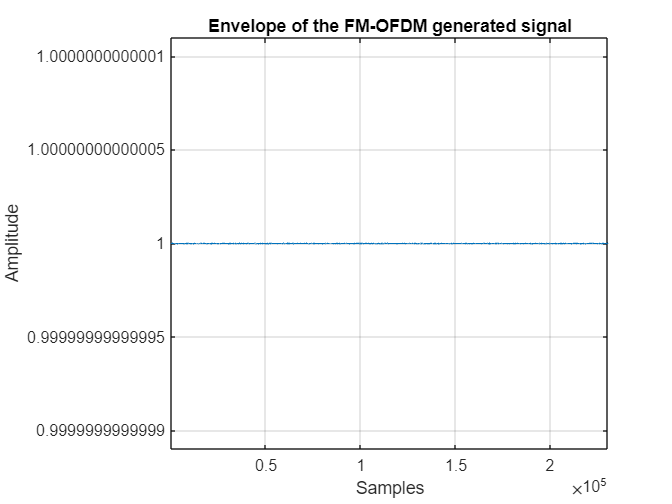

figure()
plot(abs(signal_fm_ofdm))
title("Envelope of the FM-OFDM generated signal") %Revisar
xlabel("Samples")

ylabel("Amplitude")
grid on;
axis tight;

Let's also plot the real an imaginary part of our FM-OFDM Signal:

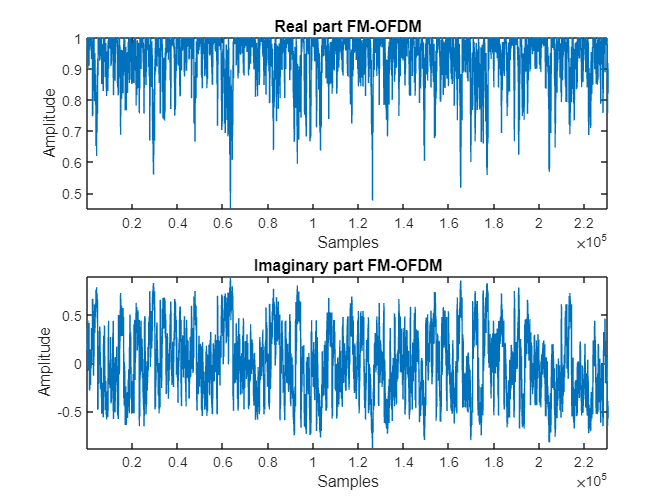

figure()
subplot(2,1,1)
plot(real(signal_fm_ofdm))
title("Real part FM-OFDM")
xlabel("Samples")
ylabel("Amplitude")
axis tight
subplot(2,1,2)
plot(imag(signal_fm_ofdm))
xlabel("Samples")

ylabel("Amplitude")
title("Imaginary part FM-OFDM")
axis tight

Finally, after generating the two FM-OFDM signals for the two different modulation index, we are going to analyze their spectrum. This will allow us to observe how the **modulation index** affects the **occupied bandwidth** of the transmitted signal.

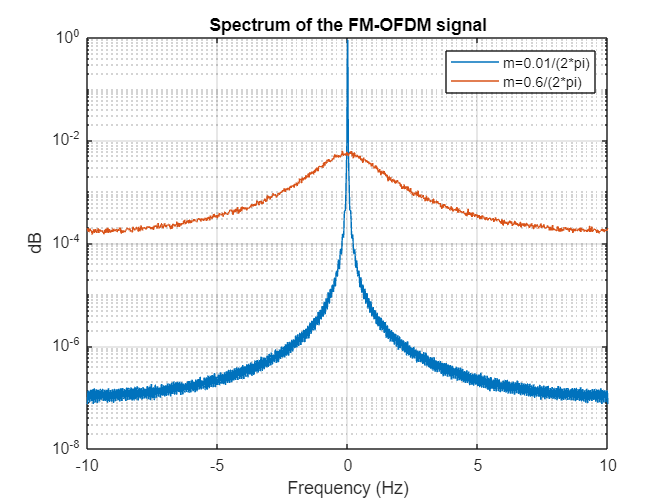

[p,f] = pspectrum(signal_fm_ofdm);
[p2,f] = pspectrum(signal_fm_ofdm2);
new_f = f ./ pi * Fs / 2;
figure()
semilogy(new_f, (p))
hold on
semilogy(new_f, (p2))
grid on
title('Spectrum of the FM-OFDM signal')

legend('m=0.01/(2*pi)','m=0.6/(2*pi)')
xlabel("Frequency (Hz)")
ylabel('dB')

The modulation index ***m*** controls the **frequency deviation** of the FM-OFDM signal. This means that, as it can be seen in the previous graph, from a spectral perspective, increasing ***m*** causes the phase variations to be more pronounced, leading to a wider frequency spread. This is way for the lowest value of the modulation index (blue), the spectrum remains **narrow**, closely similar to the one obtained for CE-OFDM. While, for higher values of ***m*** (orange), the signal exhibits a higher bandwidth, so the energy is spread over a larger frequency range. For this reason, when increasing the value of ***m***, the phase variations are increased, causing a more significant frequency spread. 